%1. load cerebus file
%2. load colortracking file
%3. align times (based on led square wave)
%4. put kinect marker locations in handle coordinates
%   -if this is the first file from the day, find the rotation matrix and then use it
%   -if not, just use the rotation matrix found from another file from the day

%Output will be all the markers in handle coordinates, and in cerebus time

## 1. LOAD CEREBUS FILE

folder = '/home/raeed/Projects/limblab/FSMRes/limblab/User_folders/Raeed/Arm Model/Data/Chips/experiment_20151120_RW_003/';

folder = 'C:\Users\rhc307\Documents\Data\Han\experiment_20160325_RW_hold\';
prefix = 'Han_20160325_RW_hold_area2_001';
labnum = 6;

bdf = get_nev_mat_data([folder prefix],labnum);

bdf.meta.task = 'RW';

opts.binsize=0.05;
opts.offset=-.015;
opts.do_trial_table=1;
opts.do_firing_rate=1;
bdf=postprocess_bdf(bdf,opts);

## 2. LOAD MOTION TRACKING FILE

load([folder 'markers_' prefix '.mat'])

%Note - this folder may be different than the one w/ the cerebus file?

## 3. ALIGN TIMES (PUT THE MOTION TRACKING FILE IN CEREBUS TIME)

## 3a. Plot LED vals

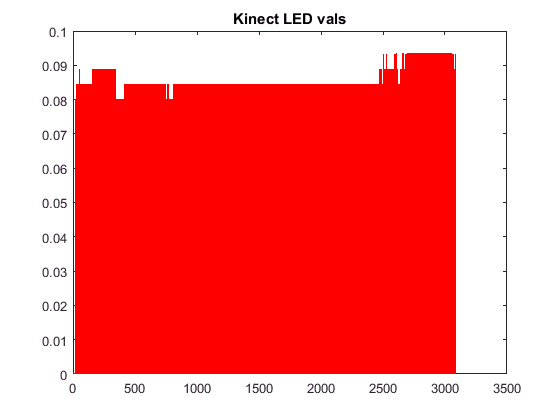

figure; plot(times,led_vals,'r');
title('Kinect LED vals')

## 3b. Enter kinect start time estimate

kinect_start_guess=19.5;

## 3c. Align kinect led values with cerebus squarewave

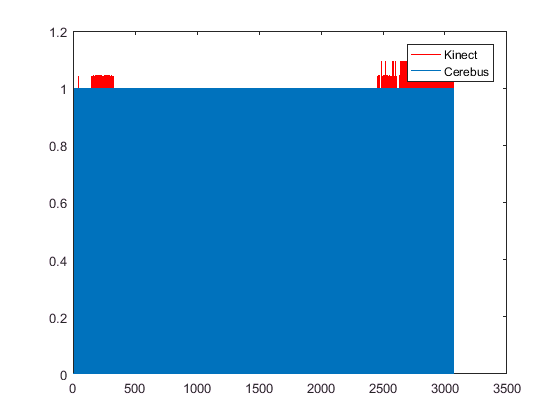

plot_flag=1; %Whether to plot the match between the kinect LED and cerebus squarewaves
kinect_times  = match_squarewave_main( bdf, led_vals, times, kinect_start_guess, plot_flag);


clear plot_flag
clear kinect_start_guess
clear led_vals
clear times

## 4. PUT KINECT MARKER LOCATIONS IN HANDLE COORDINATES

rotation_known=0; %Whether the rotation matrix is already known (from another file from that day)

## 4a. Plot handle to determine some points to remove

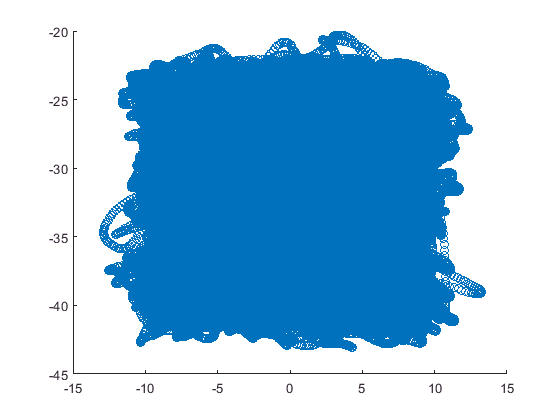

%We want to remove the time points when the monkey has thrown away the
%handle, since then the hand won't be at the same position as the handle
if ~rotation_known
    figure; scatter(bdf.pos(1:10:end,2),bdf.pos(1:10:end,3))
%Note- this plot can be removed if the limits (below) are always the same
end

## 4b. Set limits of handle points

%We'll remove times when the handle is outside these limits
if ~rotation_known
    x_lim_handle=[-10,10]; %x limits (min and max)
    y_lim_handle=[-42,-22]; %y limits (min and max)
end

## 4c. Get Translation and Rotation


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the default value of the step size tolerance and constraints are 
satisfied to within the default value of the constraint tolerance.

<stopping criteria details>



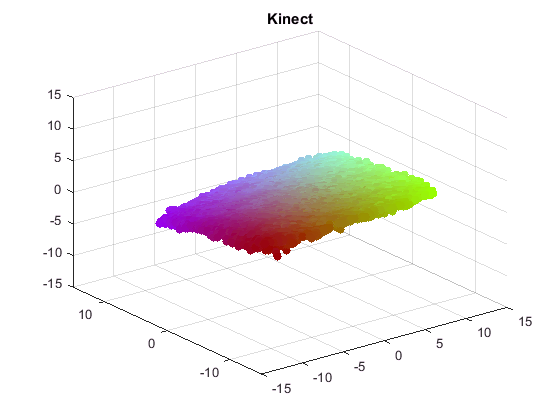

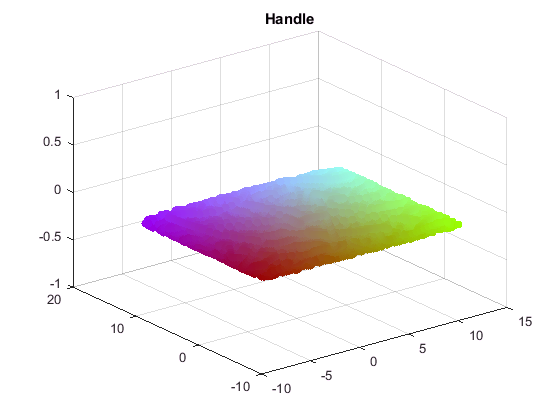

if ~rotation_known
    plot_flag=1;
    [ R, Tpre, Tpost, times_good, pos_h, colors_xy ] = get_translation_rotation( bdf, kinect_times, all_medians, x_lim_handle, y_lim_handle, plot_flag );
    %Save a file w/ T and R, so it can be used for other files from the
    %same day
    save([folder prefix '_kinect_rotation.mat'],'R','Tpre','Tpost')
else
    %Else load a file that has T and R
    load([folder prefix '_kinect_rotation.mat']);
end

## 4d. Perform Translation and Rotation on the kinect data

if ~rotation_known
    plot_flag=1;
    [ kinect_pos ] = do_translation_rotation( all_medians, R, Tpre, Tpost, plot_flag, times_good, pos_h, colors_xy );
end

if rotation_known
    [ kinect_pos ] = do_translation_rotation( all_medians, R, Tpre, Tpost);
end

clear R
clear Tpre
clear Tpost
clear plot_flag
clear rotation_known

## 5. SMOOTH OUT MARKERS

kinect_pos_smooth=NaN(size(kinect_pos));
for i=1:10
    for j=1:3
        temp=reshape(kinect_pos(i,j,:),[1,size(kinect_pos,3)]);
        kinect_pos_smooth(i,j,:)=medfilt1nan(temp,5);
    end
end

clear temp

## 5. FIND TIMES TO EXCLUDE (BECAUSE THE MONKEY THREW AWAY THE HANDLE)

## 5a. Calculate the distances of the hand marker to the handle (and plot)

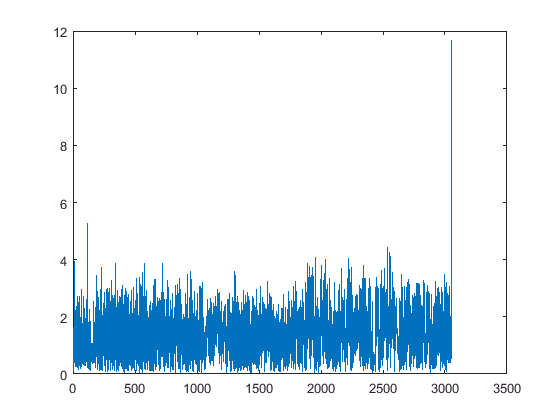

%This can be used to determine times when the monkey has thrown away the
%handle

n_times = size(all_medians,3);
k=reshape(kinect_pos(3,:,:),[3,n_times]);
h=interp1(bdf.pos(:,1),bdf.pos(:,2:3),kinect_times);
h(:,3)=0;

err=NaN(1,n_times);
for i=1:n_times    
    err(i)=pdist2(k(:,i)',h(i,:));
end

figure; plot(kinect_times,err)

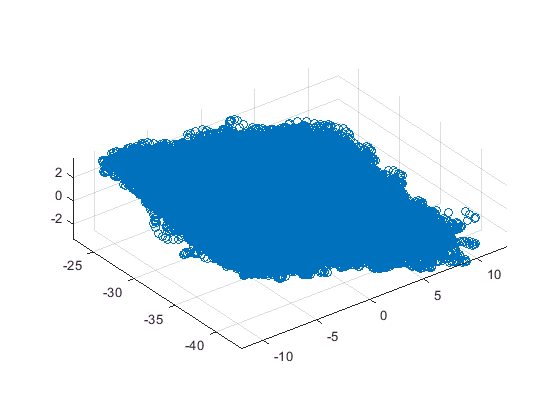

figure; scatter3(kinect_pos_smooth(3,1,:),kinect_pos_smooth(3,2,:),kinect_pos_smooth(3,3,:))
axis equal

%This can be used in combination w/ the z-force

clear err
clear n_times
clear h
clear k

## 6. PUT KINECT DATA INTO OPENSIM COORDINATES

% Robot coordinates:
% Origin at shoulder joint center of robot, x is to right, y is towards screen, z is up
% OpenSim coordinates:
% Origin at shoulder joint center (marker 9), x is towards screen, y is up, z is to right

% extract and clean up shoulder jc data
shoulder_pos = squeeze(kinect_pos_smooth(9,:,:))';
marker_loss_points = find(diff(isnan(shoulder_pos(:,1)))>0);
marker_reappear_points = find(diff(isnan(shoulder_pos(:,1)))<0);
if(~isempty(marker_loss_points) || ~isempty(marker_reappear_points))
    if length(marker_loss_points)>length(marker_reappear_points) || marker_loss_points(end)>marker_reappear_points(end)
        %Means that a marker was lost but never found again at end of file
        %append last index
        marker_reappear_points(end+1) = length(shoulder_pos);
    end
    if length(marker_loss_points)<length(marker_reappear_points) || marker_loss_points(1)>marker_reappear_points(1)
        %Means that a marker was lost to start
        %Dont know what to do here other than put a zero at start off loss
    %     marker_reappear_points(1) = [];
        marker_loss_points = [0;marker_loss_points];
        warning('Shoulder position marker not found at start of file. Replacing missing start points with first reappearance position')
    end
    for i=1:length(marker_loss_points)
        marker_loss = marker_loss_points(i);
        marker_reappear = marker_reappear_points(i);
        num_lost = marker_reappear-marker_loss;
        if marker_loss~=0
            rep_coord = repmat(shoulder_pos(marker_loss,:),num_lost,1);
        else
            rep_coord = repmat(shoulder_pos(marker_reappear,:),num_lost,1);
        end
        shoulder_pos(marker_loss+1:marker_reappear,:) = rep_coord;
    end
end

% Recenter all markers on shoulder position
rep_shoulder_pos = repmat(shoulder_pos,[1 1 11]);
rep_shoulder_pos = permute(rep_shoulder_pos,[3 2 1]);
kinect_pos_recenter = kinect_pos_smooth-rep_shoulder_pos;

% switch axes of coordinate frame
% x->z, y->x, z->y
kinect_pos_opensim = kinect_pos_recenter(:,[2 3 1],:);
% kinect_pos_opensim(:,1,:) = kinect_pos_recenter(:,2,:); % new x=old y
% kinect_pos_opensim(:,2,:) = kinect_pos_recenter(:,3,:); % new y=old z
% kinect_pos_opensim(:,3,:) = kinect_pos_recenter(:,1,:); % new z=old x

% change from cm to meters
kinect_pos_opensim = kinect_pos_opensim/100;

## extract target data (ONLY FOR RANDOM WALK TASKS!!)

if(strcmp(bdf.meta.task,'RW'))
    target_on_off = bdf.TT(:,[bdf.TT_hdr.go_cues bdf.TT_hdr.end_time]);
    % target_on = reshape(target_on',length(target_on(:)),1); % reshape into column vector
    % target_off = bdf.TT(:,bdf.TT_hdr.end_time);
    target_pos_on = bdf.targets.centers(:,3:end);
    % target_pos_on = reshape(target_pos_on',2,4*length(target_pos_on))';
    % target_pos_on = [target_pos_on zeros(length(target_pos_on),1)]; %add z axis
%     num_targets = bdf.TT(:,bdf.TT_hdr.num_targets);
    num_attempted = bdf.TT(:,bdf.TT_hdr.num_targets_attempted);
    xy_offset = [bdf.TT(:,bdf.TT_hdr.x_offset) bdf.TT(:,bdf.TT_hdr.y_offset)];
    
    % expand target data to framerate
    % prefill with NaNs
    target_pos = NaN(length(kinect_times),3);
    % loop through trials
    for i=1:length(target_on_off)
        for j=1:num_attempted(i) % cycle through targets in trial
            % find position offset
            on_time = target_on_off(i,j);
            next_time = target_on_off(i,j+find(target_on_off(i,j+1:end)~=-1,1)); % find next target time that hasn't been aborted in this trial
            target_in_frame = kinect_times>on_time & kinect_times<next_time; % find frame times that are in this target
            target_pos(target_in_frame,:) = repmat([target_pos_on(i,2*j-1:2*j)-xy_offset(i,:) 0],sum(target_in_frame),1); % extract target for this time, replicate it for number of frames, and place in new target array
        end
    end
    
elseif(strcmp(bdf.meta.task,'CO'))
    target_on_off = bdf.TT(:,[bdf.TT_hdr.ot_time bdf.TT_hdr.end_time]);
    target_pos_on = [mean(bdf.targets.corners(:,[2 4]),2) mean(bdf.targets.corners(:,[3 5]),2)]; % calculate target centers
    
    % FILL THIS IN LATER
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    target_pos = NaN(length(kinect_times),3);
end

% Recenter targets on shoulder position
% target_shoulder_rep = interp1(kinect_times,shoulder_pos,target_on_off);
recenter_target_pos = target_pos-shoulder_pos;

% switch axes and convert from cm to meters
% x->z, y->x, z->y
target_opensim = recenter_target_pos(:,[2 3 1])/100;
% kinect_target_opensim(:,1,:) = kinect_target_pos(:,2,:); % new x=old y
% kinect_target_opensim(:,2,:) = kinect_target_pos(:,3,:); % new y=old z
% kinect_target_opensim(:,3,:) = kinect_target_pos(:,1,:); % new z=old x

% do same for handle position
handle_pos = [bdf.pos(:,2:3) zeros(length(bdf.pos),1)];
handle_pos=interp1(bdf.pos(:,1),handle_pos,kinect_times);
recenter_handle = handle_pos-shoulder_pos;
handle_opensim =  recenter_handle(:,[2 3 1])/100;

## clear variables for space

clear kinect_pos_recenter
clear rep_shoulder_pos
clear rep_coord
clear marker_loss_points
clear marker_reappear_points
clear marker_loss
clear marker_reappear
clear num_lost
clear shoulder_pos

clear target_pos
clear on_time
clear next_time
clear target_in_frame
clear recenter_target_pos
clear handle_pos
clear recenter_handle
clear num_targets
clear num_attempted
clear target_on_off
clear target_pos_on
clear i
clear j

## 7. FIND BAD HAND FRAMES

% throw away all frames that have 1 or fewer hand markers
good_frame = true(size(kinect_pos_smooth,3),1);
for i=1:length(good_frame)
    if sum(isnan(kinect_pos_smooth(1:5,1,i)))>3
        good_frame(i) = false;
    end
    
    if sum(isnan(kinect_pos_smooth(1:3,1,i)))>1
        good_frame(i) = false;
    end
end

## 7. PUT KINECT DATA INTO BDF

## 8. PUT KINECT MOTION TRACKING DATA INTO TRC FORMAT

% find meta data
frame_rate = 1/mean(diff(kinect_times));
num_markers = 10; % ONLY USED 10 MARKERS FOR CHIPS DATA
start_idx = find(kinect_times>=0,1,'first');
num_frames = length(kinect_times)-start_idx+1;
marker_names = {'Marker_1','Marker_2','Marker_3','Marker_4','Marker_5','Marker_6','Marker_7','Marker_8','Shoulder JC','Pronation Pt1'};

% open file and write header
fid = fopen([folder prefix '.trc'],'w');
fprintf(fid,['PathFileType\t4\tX/Y/Z\t' prefix '.trc\n']);
fprintf(fid,'DataRate\tCameraRate\tNumFrames\tNumMarkers\tUnits\tOrigDataRate\tOrigDataStartFrame\tOrigNumFrames\n');
fprintf(fid,'%5.2f\t%5.2f\t%d\t%d\tm\t%5.2f\t%d\t%d\n',[frame_rate frame_rate num_frames num_markers frame_rate 1 num_frames]);

% write out data header
fprintf(fid,'Frame#\tTime\t');
for i = 1:num_markers
    fprintf(fid,'%s\t\t\t',marker_names{i});
end
fprintf(fid,'\n');
fprintf(fid,'\t\t');
for i = 1:num_markers
    fprintf(fid,'X%d\tY%d\tZ%d\t',[i,i,i]);
end
fprintf(fid,'\n\n');

% write out data
for j=1:num_frames
    frame_idx = j-1+start_idx;
    if(good_frame(frame_idx))
        fprintf(fid,'%d\t%f\t',[j kinect_times(frame_idx)]);
        marker_pos = kinect_pos_opensim(1:num_markers,:,frame_idx);
        for i = 1:num_markers
            if isnan(marker_pos(i,1))
                fprintf(fid,'\t\t\t');
            else
                fprintf(fid,'%f\t%f\t%f\t',marker_pos(i,:));
            end
        end
        fprintf(fid,'\n');
    end
end

% close file
fclose(fid);
clear fid

## 9. PUT TARGET DATA INTO TRC FORMAT

% find meta data
frame_rate = 1/mean(diff(kinect_times));
start_idx = find(kinect_times>=0,1,'first');
num_frames = length(kinect_times)-start_idx+1;
% marker_names = {'Marker_1','Marker_2','Marker_3','Marker_4','Marker_5','Marker_6','Marker_7','Marker_8','Shoulder JC','Pronation Pt1'};
marker_names = {'Handle', 'Target'};
num_markers = length(marker_names); % ONLY USED 10 MARKERS FOR CHIPS DATA

% open file and write header
fid = fopen([folder prefix '_targets.trc'],'w');
fprintf(fid,['PathFileType\t4\tX/Y/Z\t' prefix '.trc\n']);
fprintf(fid,'DataRate\tCameraRate\tNumFrames\tNumMarkers\tUnits\tOrigDataRate\tOrigDataStartFrame\tOrigNumFrames\n');
fprintf(fid,'%5.2f\t%5.2f\t%d\t%d\tm\t%5.2f\t%d\t%d\n',[frame_rate frame_rate num_frames num_markers frame_rate 1 num_frames]);

% write out data header
fprintf(fid,'Frame#\tTime\t');
for i = 1:num_markers
    fprintf(fid,'%s\t\t\t',marker_names{i});
end
fprintf(fid,'\n');
fprintf(fid,'\t\t');
for i = 1:num_markers
    fprintf(fid,'X%d\tY%d\tZ%d\t',[i,i,i]);
end
fprintf(fid,'\n\n');

% write out data
for j=1:num_frames
    frame_idx = j-1+start_idx;
    fprintf(fid,'%d\t%f\t',[j kinect_times(frame_idx)]);
    
    % print handle position
    if isnan(handle_opensim(frame_idx,1))
        fprintf(fid,'\t\t\t');
    else
        fprintf(fid,'%f\t%f\t%f\t',handle_opensim(frame_idx,:));
    end
    
    %print target position
    if isnan(target_opensim(frame_idx,1))
        fprintf(fid,'\t\t\t');
    else
        fprintf(fid,'%f\t%f\t%f\t',target_opensim(frame_idx,:));
    end
    fprintf(fid,'\n');
end

% close file
fclose(fid);
clear fid